**1.    Statistische Momente des Grauwerthistogramms (ca. 45 Minuten)**

In dieser Aufgabe werden Sie die statistischen Momente des Grauwerthistogramms mit Hilfe von MATLAB implementieren und für verschiedene Bilder anwenden. Sie können dazu das vorbereitete Skript „Textureigenschaften.m“ verwenden.

- Implementieren Sie die Kenngrößen Mittelwert, Varianz und Entropie! Nutzen Sie dazu die MATLAB-Funktionen `mean `bzw.` mean2`, `var` und `entropy`. Testen Sie Ihr Programm mit Hilfe der Bilder 1-4 und interpretieren Sie die Ergebnisse! Warum ist es nicht möglich, die Bilder 1, 2 und 4 mit Hilfe dieser Kenngrößen voneinander zu unterscheiden?

*Hinweis: Mit *`img(:)` *können Sie die Bildmatrix in einen Vektor überführen, um o.g. Funktionen nutzen zu können*.

## 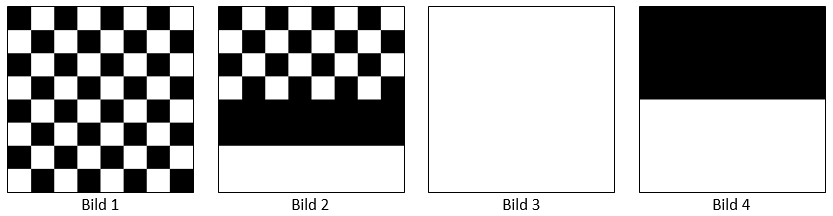

    clear
    clc
% 
% %     mean = zeros(10, 1);
% %     var = zeros(10, 1);
% %     entropy = zeros(10, 1);
%     results = zeros(10, 4);
%     for i=5:10
%         i;
%         bild_nr = i;
%         img_name = ['../Bilder/Bild', num2str(bild_nr), '.png'];   % bild einlesen
%         img = imread(img_name);
%         figure
%         imshow(img)
%         hold on
%         if (size(img,3)==3)     %auf einen kanal reduzieren und auf werte zwischen 0 und 1 normieren
%             img = rgb2gray(img);
%         end 
%         figure
%         histogram(img)
%         hold on
%         I = double(img(:));
%         meanValue = mean2(img)
%         varValue = var(I)
%         entropyValue = entropy(img)
%         results(i, 1) ;= i
%         results(i, 2) = meanValue;
%         results(i, 3) = varValue;
%         results(i, 4) = entropyValue;
%         offset = [0 1];
%         NumLevels = 16;
%         % GrayLimits 将输入图像缩放到灰度级所使用的范围，指定为二元素向量 [low high]
%         % NumLevels 灰度级的数量，指定为正整数
%         glcms = graycomatrix(I, 'NumLevels', NumLevels, 'Offset', offset);
%         stats = graycoprops(glcms, {'Contrast', 'Correlation', 'Homogeneity', 'Energy'});
% %         figure
% %         imshow(rescale(SI))
% %         hold on
%         disp(glcms)
%         disp(stats)
%     end
% disp('Mittelwert Varianz Entropie');
% resultsTable = array2table(results, 'VariableNames', {'i','Mittelwert', 'Varianz', 'Entropie'});
% disp(resultsTable)

- Die Bilder 5-10 sind verschiedene Realbeispiele: Steinstrand, Krokodilleder, Gras, Gasbeton, Teppich und Holz. Berechnen Sie für diese Bilder die statistischen Momente und diskutieren Sie, wie Sie die verschiedenen Texturen anhand der Kenngrößen unterscheiden können!

- Der **Mittelwert** (Mittelwerte einer Pixel-Intensität) ist eine statistische Größe, die das durchschnittliche Helligkeitsniveau einer Bildtextur beschreibt. **Je höher der Mittelwert, desto hellere Textur wird dargestellt. 平均值（一个像素强度的平均值）是一个统计量，描述了图像纹理的平均亮度水平。平均值越高，显示的纹理就越亮。**

- Die **Varianz** beschreibt die Streuung der Pixel-Intensitäten um den Mittelwert. Eine hohe Varianz zeigt an, dass die Pixel-Intensitäten stark schwanken und eine breitere Streuung haben, was auf eine komplexere Textur hinweist. Eine niedrige Varianz zeigt hingegen an, dass die Pixel-Intensitäten ähnlich sind und eine engere Streuung haben, was auf eine einfachere Textur hinweist. 方差描述了像素强度在平均值周围的分散情况。高方差表明像素强度波动强烈，且分布更广，表明纹理更复杂。另一方面，低方差表明像素强度相似，且分布较窄，表明纹理较简单。

- Die **Entropie** ist ein Maß für die Unordnung oder die Anzahl der möglichen Zustände in einer Bildtextur. Eine hohe Entropie zeigt an, dass es viele mögliche Pixel-Intensitäten gibt und dass die Textur komplex ist. Eine niedrige Entropie zeigt hingegen an, dass es wenige mögliche Pixel-Intensitäten gibt und dass die Textur einfach ist. 熵是对图像纹理中的无序或可能状态数量的衡量。高熵表明有许多可能的像素强度，纹理是复杂的。另一方面，低熵表明可能的像素强度很少，纹理很简单。

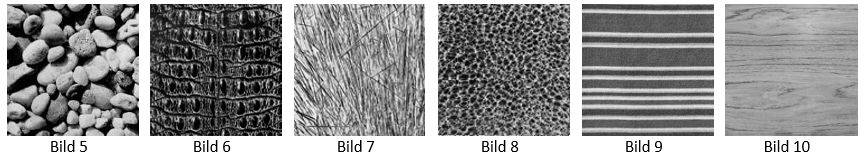

**2.    Eigenschaften der Kookkurrenzmatrix (ca. 45 Minuten)**

In dieser Aufgabe werden Sie sich eingehender mit Kookkurrenzmatrizen und den daraus ableitbaren Kenngrößen beschäftigen.

共生矩阵是一个对称矩阵，且主对角线的元素值为2的倍数

- Berechnen Sie zunächst von Hand die Kookkurrenzmatrix in horizontaler Richtung (Offset [0, 1]) für ein Bild mit einer Bittiefe von 2 Bit! Das Bild setzt sich aus den folgenden Grauwerten zusammen:

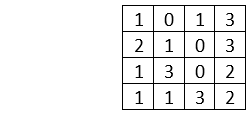

% I = [ 1 0 1 3; 2 1 0 3; 1 3 0 2; 1 1 3 2]
% mean2(I)
% double(I(:));
% var(double(I(:)))
% entropy(I)
% offsets = [0 1];
% glcm = graycomatrix(I,'Offset',offsets,'NumLevels',4,'GrayLimits',[])
% stats = graycoprops(glcm, {'Contrast', 'Correlation', 'Homogeneity', 'Energy'})

Erweitern Sie nun Ihr Skript aus Aufgabe 1 um die Berechnung und Anzeige der Kookkurrenzmatrix! Verwenden Sie die Funktion `graycomatrix` für die Berechnung. Mit dem Parameter `Offset` können Sie die Nachbarschaft bestimmen. Testen Sie das Skript mit Hilfe der verfügbaren Bilder und variieren Sie zusätzlich den Parameter `NumLevels`. Was macht dieser Parameter und welche Einstellung finden Sie sinnvoll?

- GrayLimits: 将输入图像缩放到灰度级所使用的范围，指定为二元素向量 `[low high]`。如果 `N` 是用于缩放的灰度级的数量，则范围 `[low high]` 划分为 `N` 个等宽 bin，每个 bin 中的值映射到一个灰度级。

- `NumLevels: `灰度级的数量，指定为正整数。例如，如果 `NumLevels` 为 `8`，则 `graycomatrix` 将 `I` 中的值缩放为 1 到 8 之间的整数。灰度级的数量决定灰度共生矩阵 (`glcm`) 的大小。数值图像的默认灰度级的数量为 `8`，逻辑图像的默认灰度级的数量为 `2`。

- Offset `[row_offset, col_offset]`: 感兴趣的像素与其邻点之间的距离，指定为由整数组成的 p×2 矩阵。矩阵中的每行均为一个二元素向量，

- 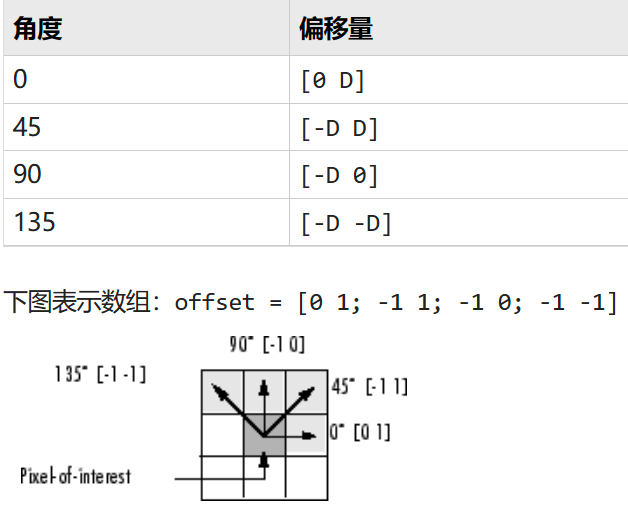

- Berechnen Sie zusätzlich die Eigenschaften der Kookkurrenzmatrix: Kontrast, Korrelation, Homogenität und Energie! Nutzen Sie dazu die Funktion `graycoprops`. Berechnen Sie die Kenngrößen für die Realbeispiele. Können die Texturen mit Hilfe dieser Kenngrößen nun besser unterschieden werden, als durch die statistischen Momente des Grauwerthistogramms?

- 参数offset决定了邻域，参数NumLevels决定了图像被量化的灰度等级的数量。共同发生矩阵被归一化，然后显示出来。

% img = imread('../Bilder/Bild2.png');  
% if (size(img,3)==3)     %auf einen kanal reduzieren und auf werte zwischen 0 und 1 normieren
%     img = rgb2gray(img);   
% end 
% 
% % Convert the image to grayscale
% I = im2gray(img);
% 
% % Define the neighborhood size and the number of gray levels
% offset = [0 1];
% NumLevels = 2;
% 
% % Calculate the co-occurrence matrix
% G = graycomatrix(I, 'NumLevels', NumLevels, 'Offset', offset);
% 
% % Normalize the co-occurrence matrix
% G = G / sum(G(:));
% 
% % Display the co-occurrence matrix
% figure
% imagesc(G);
% colormap(gray);

**3.    Gemeinsames Experimentieren am Versuchsstand (ca. 45 Minuten)**

Für die Inspektion von Endlosmaterialien werden typischerweise Zeilenkameras benutzt. Die in der Übung verwendete Prosilica GC 1290C ist zwar eine Matrixkamera, kann aber auch als Zeilenkamera konfiguriert werden. Dabei werden Bilder mit einer Höhe von einem Pixel aufgenommen und anschließend für die Verarbeitung zusammengesetzt. Auf das zusammengesetzte Bild können dann die bei den vorherigen Aufgaben getesteten Kenngrößen verwendet werden. Hierzu sollen zunächst theoretische Betrachtungen gemacht werden und diese dann kurz gemeinsam mit dem Übungsleiter am Versuchsstand validiert werden.

线扫描相机通常用于连续材料的检测。演习中使用的Prosilica GC 1290C是一台矩阵相机，但也可以被配置为线扫描相机。在这种情况下，采集的图像高度为一个像素，然后进行合成处理。然后可以将前面任务中测试的参数应用于合成图像。首先要进行理论上的考虑，然后和培训师一起在试验台上进行简单的验证。

- Um die Zeilenbilder zu einem unverzerrten Bild zusammensetzen zu können, muss die Framerate der Kamera auf die Laufgeschwindigkeit des Materials abgestimmt werden. Die Framerate hängt im Freerun-Modus der Kamera maßgeblich von der eingestellten Belichtungszeit ab. Das Material bewegt sich bei unserem Aufbau mit 5 mm/s am Umfang des Zylinders. Die Optiken sind so gewählt, dass 640 Pixel im Bild 106 mm am Objekt entsprechen. Berechnen Sie die Framerate mit der die Bilder aufgenommen werden müssen, um eine unverzerrte Darstellung zu erreichen!

- 为了能够将线条图像组成一个不失真的画面，摄像机的帧率必须根据材料的运行速度进行调整。在相机的自由运行模式下，帧率主要取决于所设定的曝光时间。在我们的设置中，材料以5毫米/秒的速度围绕圆柱体的圆周运动。光学器件的选择是为了使图像中的640个像素对应于物体上的106毫米。计算为实现不失真的表现而必须拍摄的图像的帧率！这就是我们的工作。

- Nun sollen Sie den Webfehler in dem schwarz-weiß gemusterten Stoff finden: 现在你要在黑白花纹的织物中找到织造的错误。

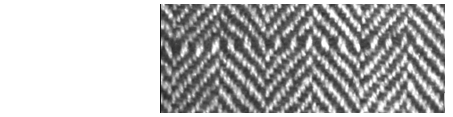

Das schräge Webmuster ist an einer Stelle unterbrochen und wird fälschlicherweise gerade fortgeführt. Dieser Fehler soll erkannt werden.

对角线编织图案在一个点上被打断，并被错误地直接延续。要检测这个错误。

- Überlegen und begründen Sie, welche Einstellungen der Kookkurrenzmatrix sinnvoll sein könnten (bzgl. `NumLevels `und `Offset`). Diskutieren Sie, welche Eigenschaft der Kookkurrenzmatrix am besten geeignet sein könnte, um den Webfehler zuverlässig zu detektieren! 考虑并证明共生矩阵的哪些设置可能是有用的（关于NumLevels和Offset）。讨论共生矩阵的哪种属性最适合于可靠地检测编织错误!

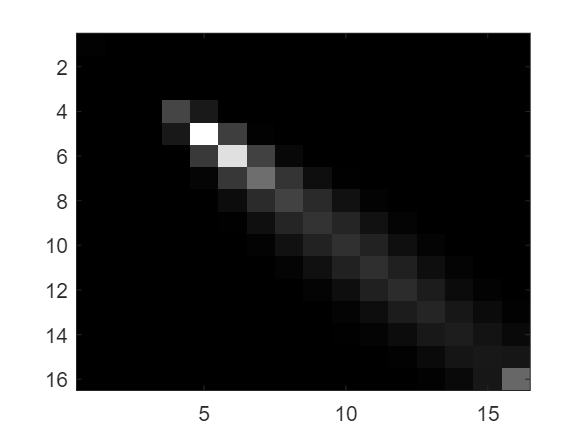

img = imread('../Bilder/Webstoff.png');  
if (size(img,3)==3)     %auf einen kanal reduzieren und auf werte zwischen 0 und 1 normieren
    img = rgb2gray(img);   
end 

% Convert the image to grayscale
I = im2gray(img);

% Define the neighborhood size and the number of gray levels
offset = [0 1];
NumLevels = 16;

% Calculate the co-occurrence matrix
G = graycomatrix(I, 'NumLevels', NumLevels, 'Offset', offset);

% Normalize the co-occurrence matrix
% G = G / sum(G(:));

% Display the co-occurrence matrix
figure
imagesc(G);
colormap(gray);


% Calculate the properties of the co-occurrence matrix
stats = graycoprops(G, {'Contrast', 'Correlation', 'Homogeneity', 'Energy'});

% Display the properties of the co-occurrence matrix
disp(stats);

       Contrast: 1.1769
    Correlation: 0.9532
         Energy: 0.0377
    Homogeneity: 0.7172



Test

% results = zeros(10, 8);
% for i=5:10
%     i;
%     bild_nr = i;
%     img_name = ['../Bilder/Bild', num2str(bild_nr), '.png'];   % bild einlesen
%     img = imread(img_name);
% %         figure
% %         imshow(img)
% %         hold on
%     if (size(img,3)==3)     %auf einen kanal reduzieren und auf werte zwischen 0 und 1 normieren
%         img = rgb2gray(img);
%     end 
%     I = double(img(:));
%     meanValue = mean2(img);
%     varValue = var(I);
%     entropyValue = entropy(img);
%     stats = graycoprops(I, {'Contrast', 'Correlation', 'Homogeneity', 'Energy'});
%     results(i, 1) = i;
%     results(i, 2) = meanValue;
%     results(i, 3) = varValue;
%     results(i, 4) = entropyValue;
%     results(i, 5) = stats.Energy;
%     results(i, 6) = stats.Correlation;
%     results(i, 7) = stats.Homogeneity;
%     results(i, 8) = stats.Contrast;
%     offsets = [0 1];
%     NumLevels = 8;
%     % GrayLimits 将输入图像缩放到灰度级所使用的范围，指定为二元素向量 [low high]
%     % NumLevels 灰度级的数量，指定为正整数
%     G = graycomatrix(img,'Offset',offsets,'NumLevels',NumLevels);
% %     figure
% %     imshow(rescale(SI))
% %     hold on
%     figure
%     imagesc(G);
%     colormap(gray);
% end
% disp('Mittelwert Varianz Entropie');
% resultsTable = array2table(results, 'VariableNames', {'i','Mittelwert', 'Varianz', 'Entropie','Energie','Koorelation','Homogenität','Kontrast'});
% disp(resultsTable)